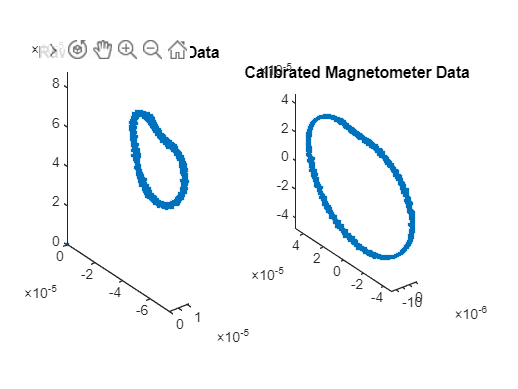

% Load raw magnetometer data (Nx3 matrix)
raw_mag = squeeze(permute(out.Sensor_MAG.signals.values, [3, 2, 1]));

% Calibrate using ellipsoid method
[calibrated_mag, params] = Calibration(raw_mag);

% Visualize results
figure;
subplot(1,2,1);
plot3(raw_mag(:,1), raw_mag(:,2), raw_mag(:,3), '.');
title('Raw Magnetometer Data'); axis equal;

subplot(1,2,2);
plot3(calibrated_mag(:,1), calibrated_mag(:,2), calibrated_mag(:,3), '.');
title('Calibrated Magnetometer Data'); axis equal;